**Problem1**

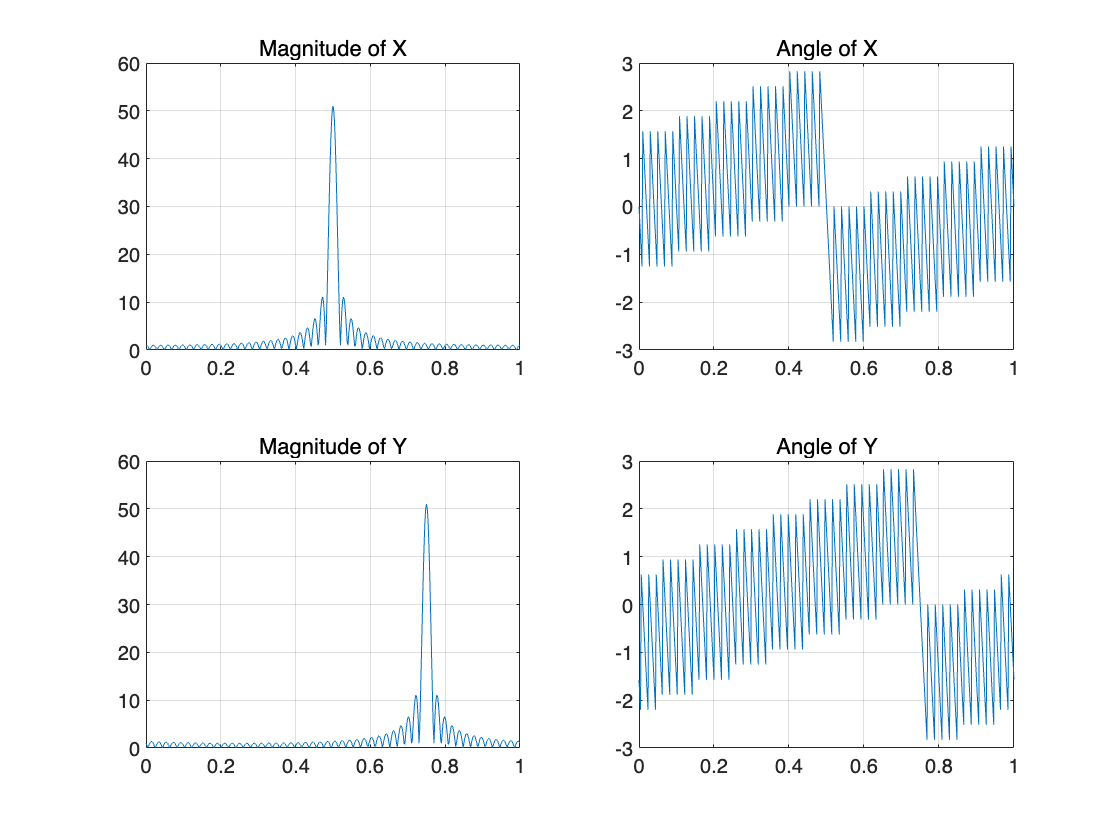

clc; clear; close all;
%신호 정의
n = 0:100;
x = cos(pi*n/2);
y = exp(1j*pi*n/4) .* x;

k = 0:500;
w = pi * k / 500;

% DTFT of x[n]
X = x * (exp(-1j*pi/500)) .^ (n' * k);

% DTFT of y[n]
Y = y * (exp(-1j*pi/500)) .^ (n' * k);

% Plot
figure(1);
subplot(2,2,1); plot(w/pi, abs(X)); title('Magnitude of X'); grid on;
subplot(2,2,2); plot(w/pi, angle(X)); title('Angle of X'); grid on;
subplot(2,2,3); plot(w/pi, abs(Y)); title('Magnitude of Y'); grid on;
subplot(2,2,4); plot(w/pi, angle(Y)); title('Angle of Y'); grid on;

clf;

y[n]의 dtft가 x[n]의 dtft에서 frequncy shift가 된 것을 magnitude와 angle 모두에서 결과로 인해 확인할 수 있다

**Problem2**

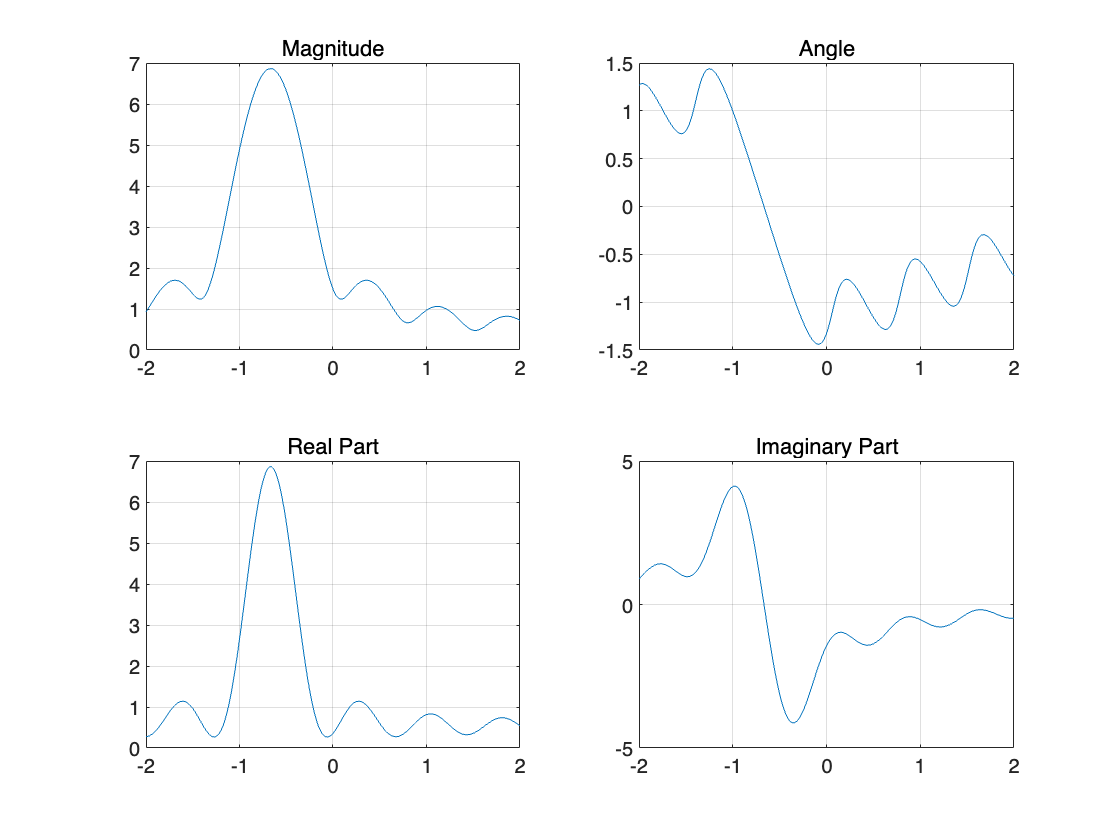

figure(2);
%신호정의
n = 0:10;
x = (0.9 * exp(1j*pi/3)) .^ n;
w = linspace(-2*pi, 2*pi, 1001);
k = 0:1000;

%DTFT
X = x * (exp(-1j * pi/1000) .^ (n'*k));
%각 성분 정리
magX = abs(X); angX = angle(X);
realX = real(X); imagX = imag(X);
%시각화
figure;
subplot(2,2,1); plot(w/pi, magX); title('Magnitude'); grid on;
subplot(2,2,2); plot(w/pi, angX); title('Angle'); grid on;
subplot(2,2,3); plot(w/pi, realX); title('Real Part'); grid on;
subplot(2,2,4); plot(w/pi, imagX); title('Imaginary Part'); grid on;

clf;

**Problem3**

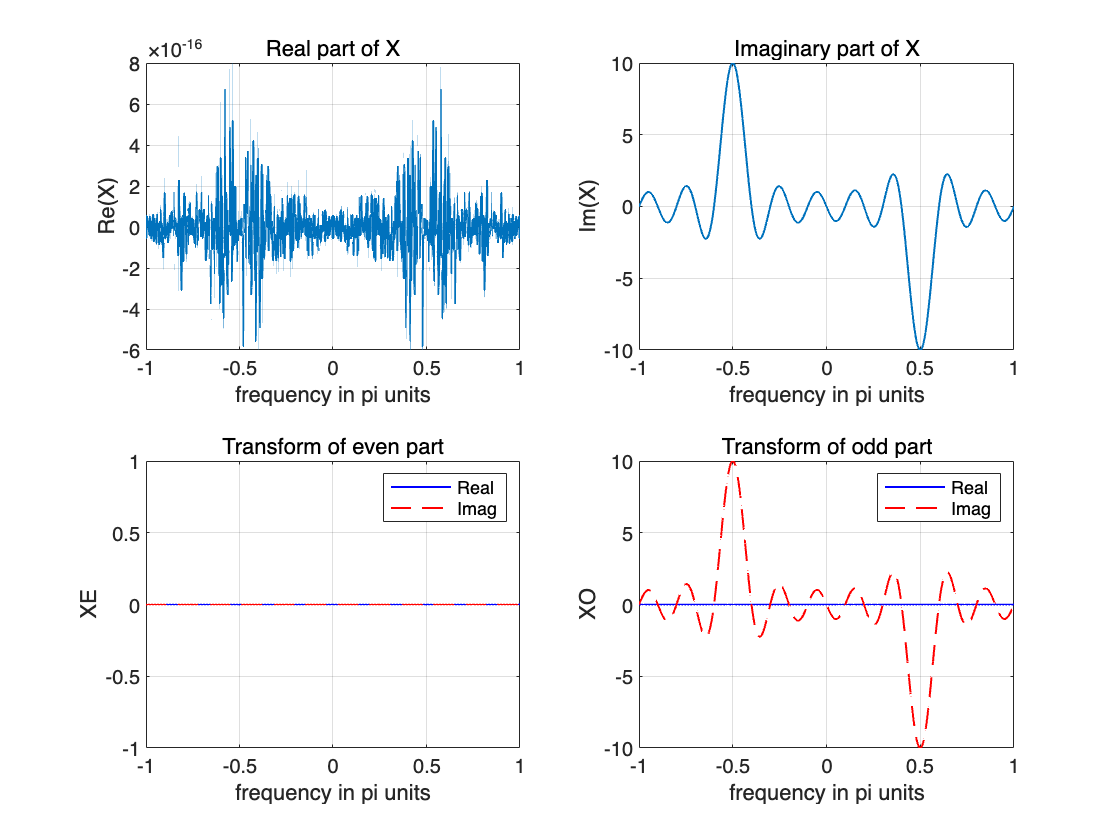

figure(3);
% 시간축 및 신호 정의
n = -10:10;
x = sin(pi * n / 2);
% Even/Odd 분해
[xe, xo, ne] = evenodd(x, n); 
% 주파수 축 생성
w = linspace(-pi, pi, 1001); 
% DTFT 계산 함수
dtft = @(sig, n, w) arrayfun(@(w0) sum(sig .* exp(-1j*w0*n)), w);
% DTFT 계산
X = dtft(x, n, w);
XE = dtft(xe, ne, w);
XO = dtft(xo, ne, w);

% Real part of X
subplot(2,2,1);
plot(w/pi, real(X), 'LineWidth', 1);
title('Real part of X');
xlabel('frequency in pi units');
ylabel('Re(X)');
grid on;
% Imag part of X
subplot(2,2,2);
plot(w/pi, imag(X), 'LineWidth', 1);
title('Imaginary part of X');
grid on;
xlabel('frequency in pi units');
ylabel('Im(X)');

% Transform of even part
subplot(2,2,3);
plot(w/pi, real(XE), 'b', 'LineWidth', 1);
hold on;
plot(w/pi, imag(XE), 'r--', 'LineWidth', 1);
grid on;
title('Transform of even part');
xlabel('frequency in pi units');
ylabel('XE');
legend('Real', 'Imag');


% Transform of odd part
subplot(2,2,4);
plot(w/pi, real(XO), 'b', 'LineWidth', 1);
hold on;
plot(w/pi, imag(XO), 'r--', 'LineWidth', 1);
grid on;
title('Transform of odd part');
xlabel('frequency in pi units');
ylabel('XO');
legend('Real', 'Imag');